RESONANCE RLC

r=0;c=1e-6;l=1e-3;
A=[-r/l -1/l; 1/c 0];
B=[1/l;0];
C=[0 1];
D=0;
rlcsystem=ss(A,B,C,D)

rlcsystem =
 
  A = 
          x1     x2
   x1      0  -1000
   x2  1e+06      0
 
  B = 
         u1
   x1  1000
   x2     0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



rlctf=tf(rlcsystem)

rlctf =
 
     1e09
  ----------
  s^2 + 1e09
 
Continuous-time transfer function.



poli=[pole(rlcsystem)]'

poli = 	1.0e+04 *

   0.0000 - 3.1623i   0.0000 + 3.1623i


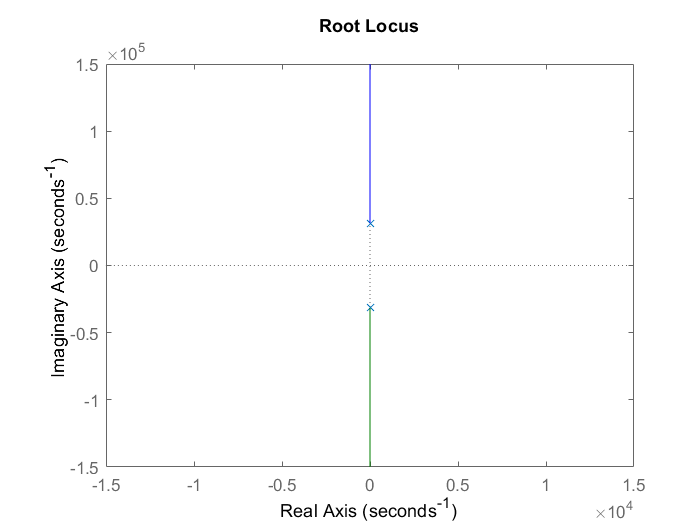

rlocus(rlctf)

damp(rlctf)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 3.16e+04i     0.00e+00       3.16e+04           Inf       
  0.00e+00 - 3.16e+04i     0.00e+00       3.16e+04           Inf       


[zeri,gain]=zero(rlcsystem);
zpgtransf=zpk(zeri,poli,gain)%%inutile in questo caso, poli complessi coniugati.

zpgtransf =
 
     1e+09
  ------------
  (s^2 + 1e09)
 
Continuous-time zero/pole/gain model.



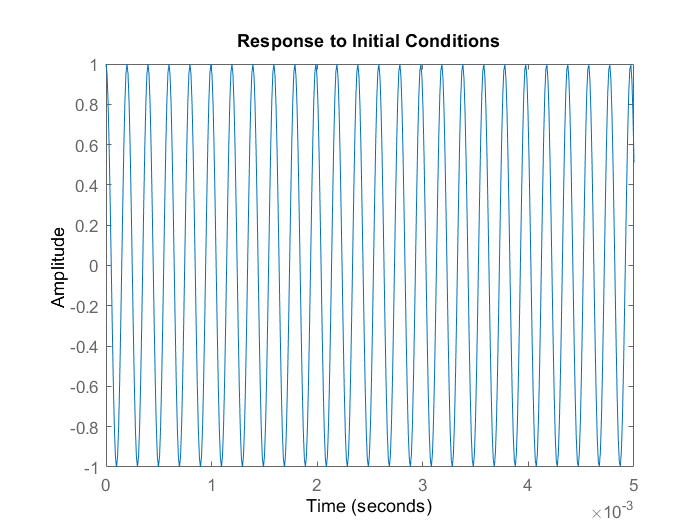

%time constant in infinite because there is no dissipation of energy =>
%r=0; l'induttore e il condensatore si scambiano reciprocamente energia
%elettrica/magnetica
initial(rlcsystem,[0;1],0.005) %%Condensatore carico e corrente iniziale nulla;

%Simuliamo il sistema quando in ingresso vi è un ingresso sinusoidale
omega=sqrt(1/(l*c)) %la pulsazione di risonanza è uguale al polo,

omega = 3.1623e+04

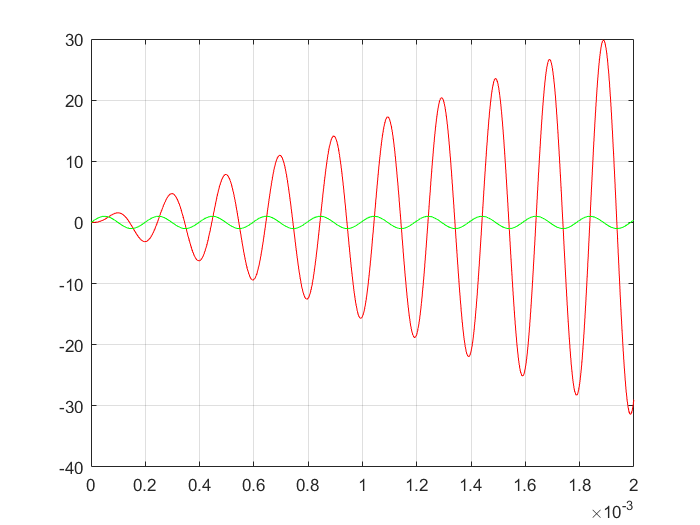

%la matrice dinamica A non è più invertibile
omega1=imag(poli(1));
f=omega/(2*pi);
tau=1/f;
[u,t]=gensig('sin',tau,0.002);
y=lsim(rlcsystem,u,t);
plot(t,y,'r',t,u,'g')
xlim('auto')
ylim('auto')
grid on 

[gpeak,fpeak]=getPeakGain(rlcsystem) %con la frequenza di risonanza si ha il più alto guadagn possibile.

gpeak = 9.5096e+15

fpeak = 3.1623e+04